## Rigid gripper experiment biasing script

This will bias the LE data of rigid_gripper_expt_2 expt_1,2,8,9,10 to get a good reading

% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

expt_file = "soft_gripper_expts_2/expt_6";
bag = ros2bagreader(expt_file);

areaSensorBag = select(bag,"Topic", "/area_sensor/float_array");
objectEncoderBag = select(bag,"Topic", "/object_linear_encoder/float_array");
areaSensorMsgs = readMessages(areaSensorBag);
objectEncoderMsgs = readMessages(objectEncoderBag);

start_time = bag.StartTime;
end_time = bag.EndTime;

sample_freq = 50;
t = (start_time:0.02:end_time)';
t_biased = t-t(1);
n = size(t,1);

### Read and display area specifically

an = size(areaSensorMsgs,1);

area = zeros(8,an,"double"); %8xn vector containing area
at = zeros(an,1,"double"); %nx1 vector containing timestamps
% first 4 is right finger, second 4 is left

for i=1:an
    at(i) = areaSensorMsgs{i}.data(1);
    area(:,i) = areaSensorMsgs{i}.data(2:9);
end

at = at - start_time;

net_area = zeros(1,an);
for i=1:8
    area(i,:) = area(i,:) - min(area(i,:));
    area(i,:) = area(i,:)/max(area(i,:));
    area(i,:) = 1e-4*area(i,:);
    net_area = area(i,:) + net_area;
end

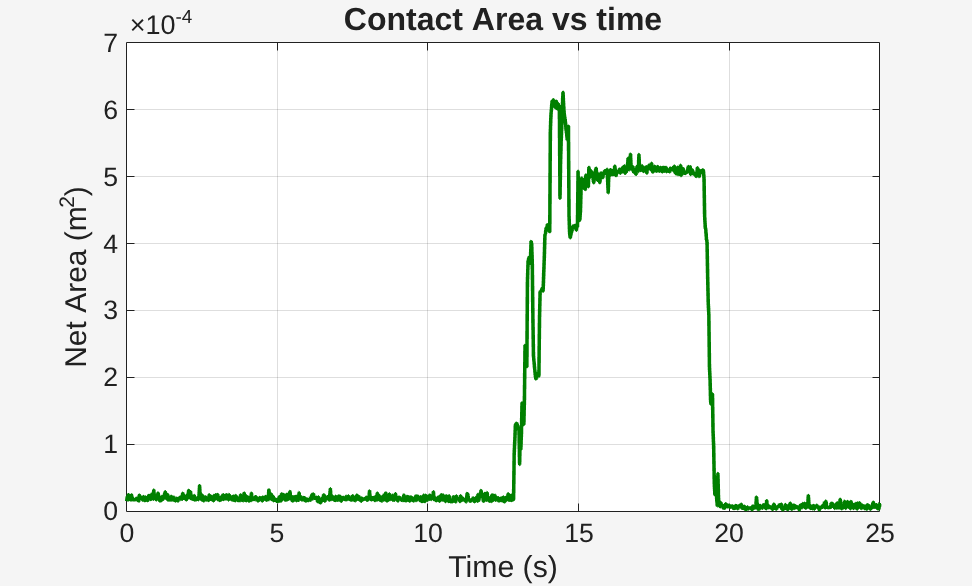

% net area over time
figure;
theme(figure,"light");
plot(at,net_area',"LineWidth",linewidth,"Color",[0 0.5 0]);
hold on;
ax = gca;
ax.FontSize = axfsz;
xlabel('Time (s)','FontSize',textfsz);
ylabel('Net Area (m^2)','FontSize',textfsz);
title('Contact Area vs time','FontSize',titlefsz-2);
xlim([0 25]);
grid on;
saveas(gcf,"Contact area over full experiment.png")
hold off;

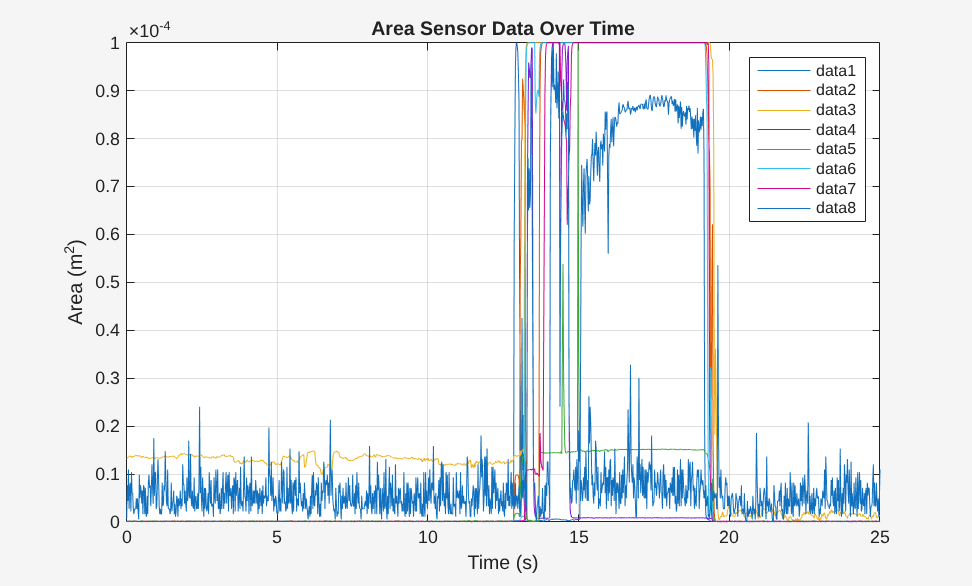


net_area = net_area';

% indv area sensor data over time
figure;
theme(figure,"light");
plot(at,area(:,:));
hold on;
legend;
xlabel('Time (s)');
ylabel('Area (m^2)');
title('Area Sensor Data Over Time');
xlim([0 25]);
grid on;
hold off;

### Read and display object linear encoder data

on = size(objectEncoderMsgs,1);

% first is left second is right
objectEncoder = zeros(2,on); % 2xn array of object data
ot = zeros(on,1); % nx1 vector containing timestamps

for i=1:on
    ot(i) = objectEncoderMsgs{i}.data(1);
    objectEncoder(:,i) = objectEncoderMsgs{i}.data(2:3);
end

ot = ot -start_time;

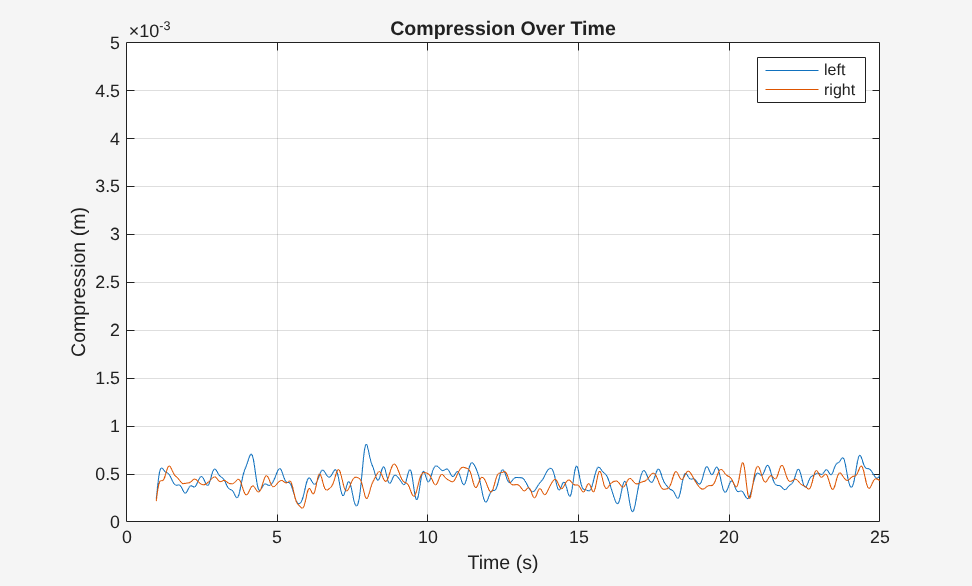

enc = (36*(objectEncoder'./3.3) - 30)./((objectEncoder'./3.3) -1);
enc(:,1) = enc(:,1) - min(enc(:,1));
enc(:,2) = enc(:,2) - min(enc(:,2));
enc = 1e-3*enc;
enc(:,1) = lowpass(enc(:,1),0.05);
enc(:,2) = lowpass(enc(:,2),0.05);


figure
theme(figure,"light");
plot(ot,enc(:,1));
hold on;
plot(ot,enc(:,2));
xlabel("Time (s)");
ylabel("Compression (m)");
xlim([0,25]);
ylim([0,5e-3]);
title("Compression Over Time");
legend(["left","right"]);
grid on;
hold off;

Transient contact finding

% create left and right bias here for each expt
bias = zeros(size(ot,1),2);

c_start_t = 12.861;
c_end_t = 15.08;

i1 = find(ot>c_start_t,1) - 90;
i2 = find(ot<c_end_t,1,"last") -90;

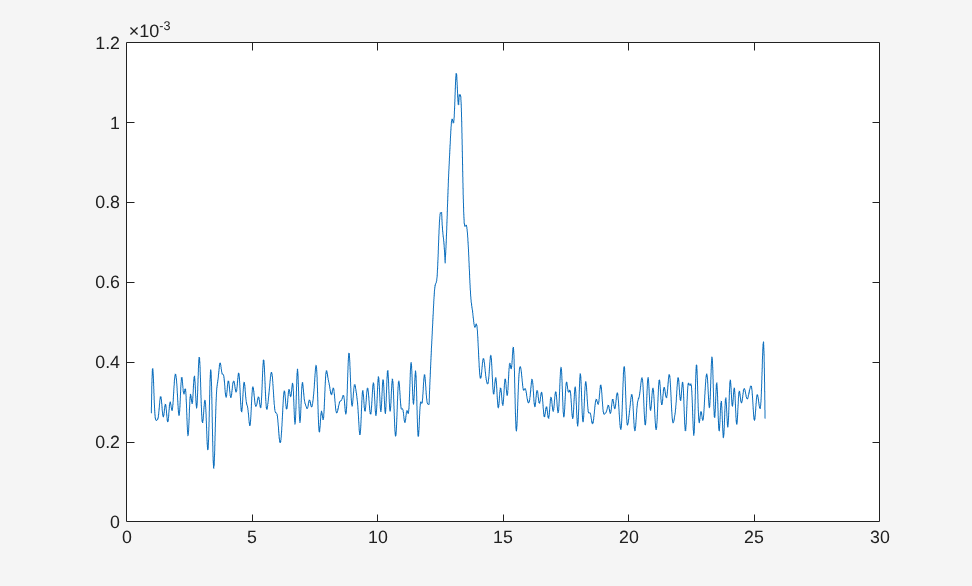

peak = 1.4e-3; % make it approx 4.5 or something

% bias shaping

% left bias
bias(1:i1+50) = peak*0.0;
bias(i1+50:uint32((i1 + i2)/2 + 20),1) = peak*0.5;
bias(uint32((i1 + i2)/2 + 20):uint32((i1 + i2)/2 + 27),1) = peak*0;
bias(uint32((i1 + i2)/2 + 27):i2,1) = peak*0.7;
bias(i2:end,1) = 0.0;

bias(:,1) = iir(bias(:,1),0.05);

noise = wgn(size(ot,1),1,0);
noise = (noise - min(noise))/(max(noise) - min(noise));
noise = 7e-4*(lowpass(noise,0.175));

bias(:,1) = bias(:,1) + noise;
plot(ot,bias(:,1));

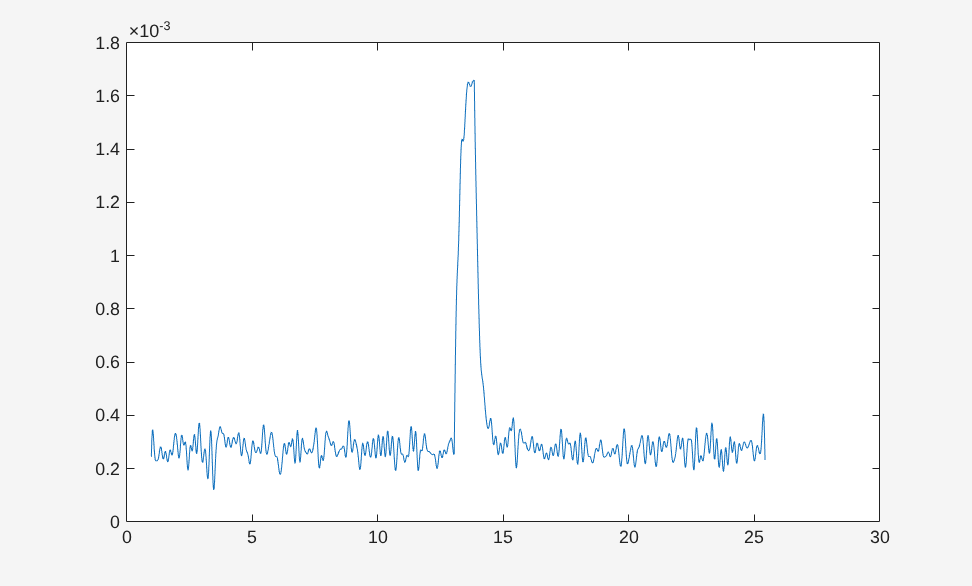

% right bias
bias(i1+100:i2+30,2) = peak;
bias(i2+30:end,2) = peak*0.0;
bias(:,2) = iir(bias(:,2),0.1);
bias(:,2) = bias(:,2) + 0.9*(noise);
plot(ot,bias(:,2));

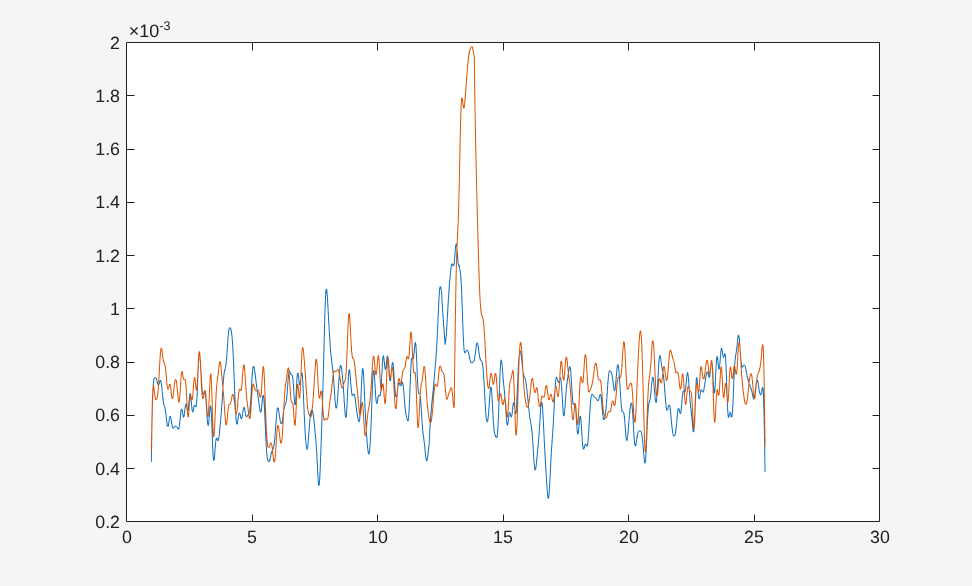

enc(:,1) = enc(:,1) + 0.7*bias(:,1);
enc(:,2) = enc(:,2) + bias(:,2);
plot(ot,enc(:,1));
hold on;
plot(ot,enc(:,2));
hold off

% save("soft_gripper_expts_2/expt_6.mat","area","enc","at","ot","i1","i2","-mat");
% after the modification is done, save enc(n,2), area(8,n), at(n,1), ot(n,1)